clc;
clear;
close all;

%%%%% Iniciar compactos %%%%%
carros(:,:,1) = im2double(rgb2gray(imread('compacto/2faf504842df_01.jpg')));
carros(:,:,2) = im2double(rgb2gray(imread('compacto/2faf504842df_05.jpg')));
carros(:,:,3) = im2double(rgb2gray(imread('compacto/2faf504842df_09.jpg')));
carros(:,:,4) = im2double(rgb2gray(imread('compacto/2faf504842df_11.jpg')));
carrosmask(:,:,1) = imread('compacto/2faf504842df_01_mask.gif');
carrosmask(:,:,2) = imread('compacto/2faf504842df_05_mask.gif');
carrosmask(:,:,3) = imread('compacto/2faf504842df_09_mask.gif');
carrosmask(:,:,4) = imread('compacto/2faf504842df_11_mask.gif');

I = carros(:,:,1);

## Marr-Hildreth

% [BW,threshOut] = edge(I,'log', 'nothinning');
% imshow(BW)


## Canny

% BW = edge(I,'Canny', 0.5, 0.1);
% imshow(BW)


## Something else

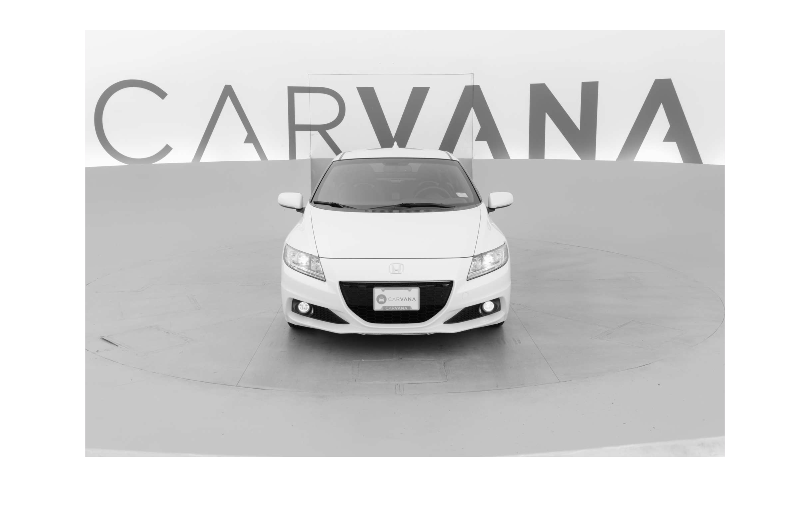

% mexer no 20 para variar o smoothing do filtro gaussiano
smoothed_image = imfilter(I, fspecial( 'gaussian', 10 ) );
imshow(smoothed_image)

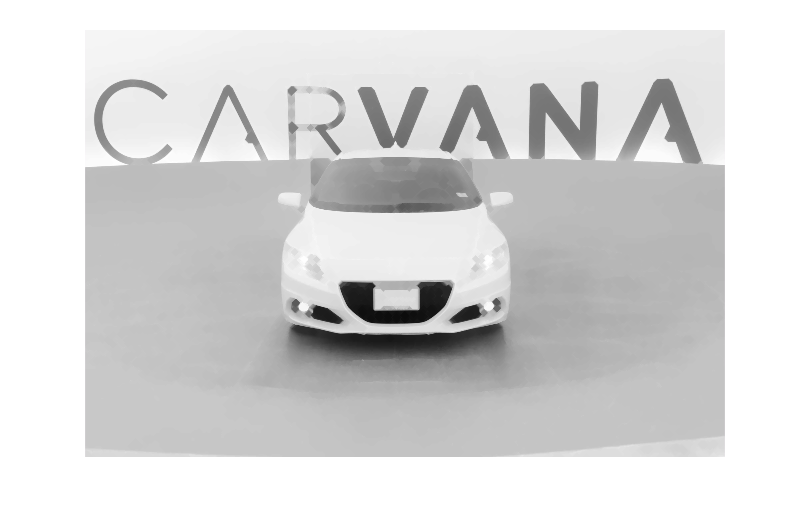


background = imclose(smoothed_image,strel('diamond', 10));
imshow(background)

% edges = edge(background, 'canny', 0.2);
% imshow(edges)